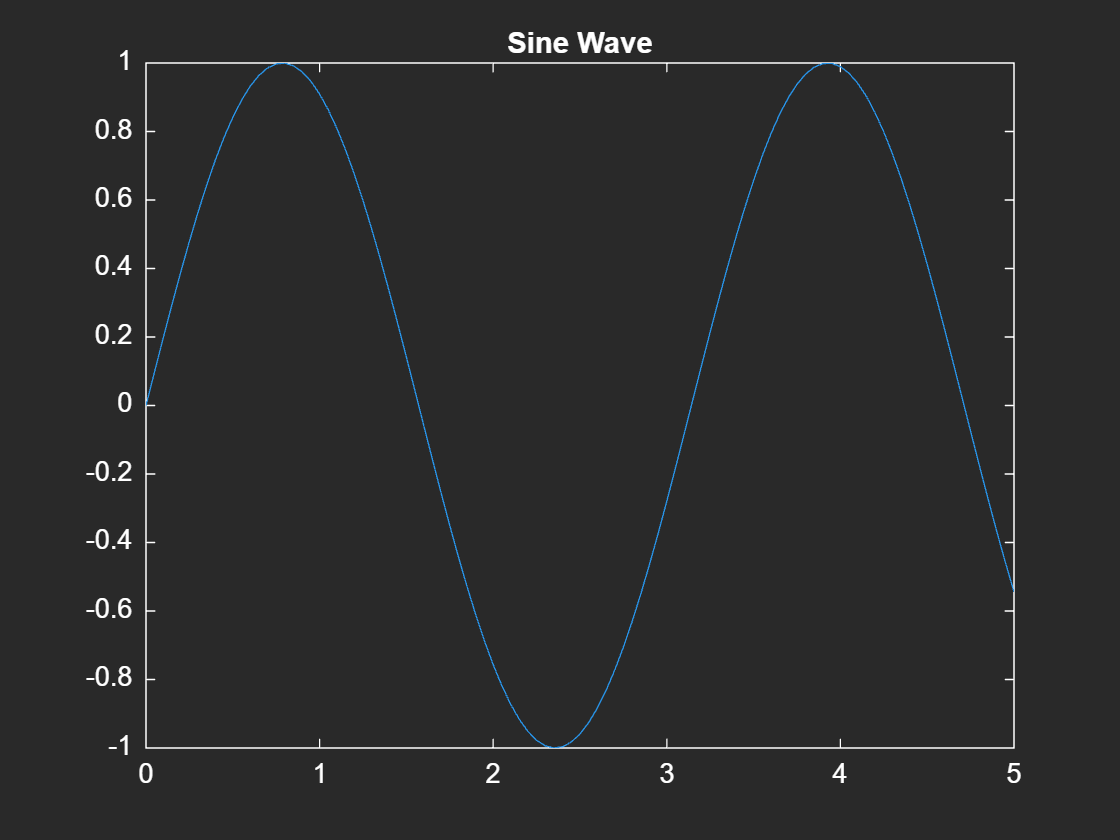

% A simple plot
figure;
x = 0:0.1:10;
y = sin(x);
plot(x, y);
plot_darkmode;
title('Sine Wave');

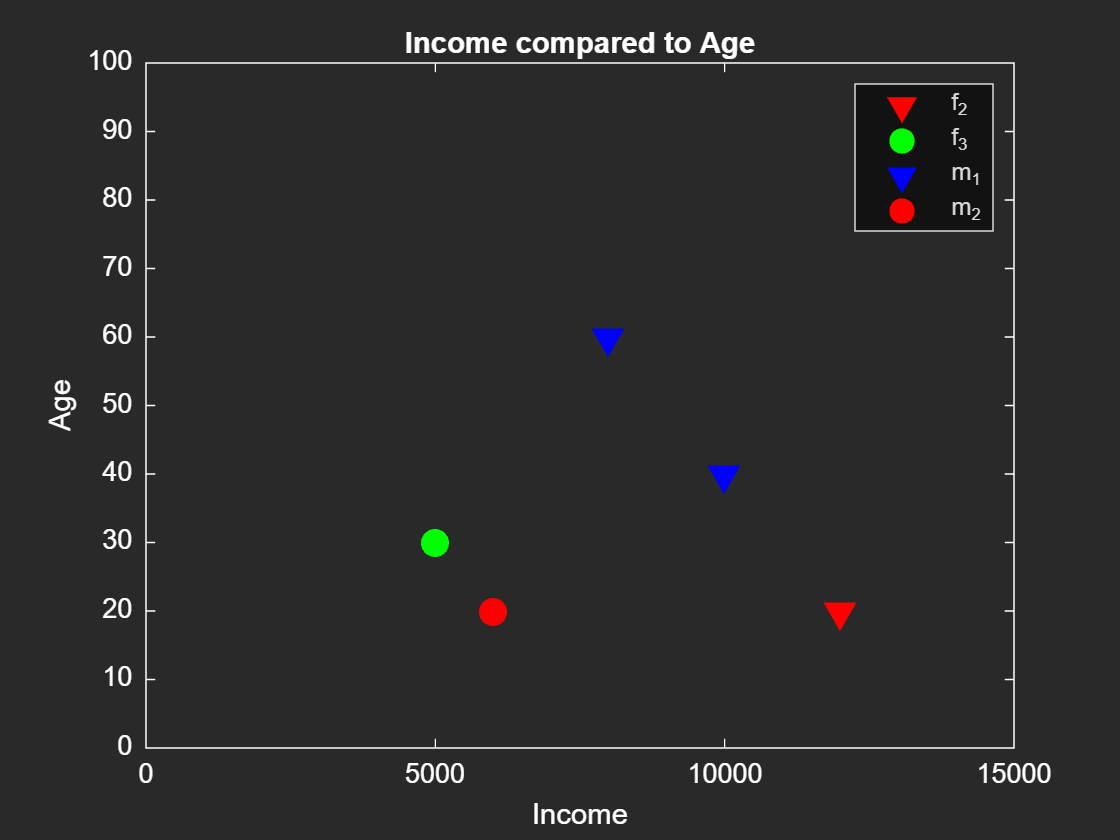

% Displaying data as scatterplot
dataTable = table( ...
    {'Adam Ammerer'; 'Anette Behrmann'; 'Bruno Bauer'; 'Betina Anker'; 'Claus Biermann'}, ...
    [10000; 12000; 8000; 5000; 6000], ...
    [40; 20; 60; 30; 20], ...
    {'m'; 'f'; 'm'; 'f'; 'm'}, ...
    [1; 2; 1; 3; 2], ...
    'VariableNames', {'Kunde', 'Einkommen', 'Alter', 'Geschlecht', 'Bonitaetsklasse'});

% Convert the data to categories
combinedGroup = strcat(string(dataTable.Geschlecht), '_', string(dataTable.Bonitaetsklasse));
combinedGroup = categorical(combinedGroup);

% Use the first and second column as coordinates
colors = ['r', 'g', 'b'];
markers = ['v', 'o', 'v', 'o', 'v'];
figure('Name', 'Income/Age Scatterplot');
gscatter(dataTable.Einkommen, dataTable.Alter, combinedGroup, colors, markers, 10, 'Einkommen', 'Alter', 'filled');
%scatter(dataTable.Einkommen, dataTable.Alter);

% Adjust the ranges of the plot
xlim([0 15000])
ylim([0 100])

% Add plot descriptions
xlabel('Income');
ylabel('Age');
plot_darkmode;
title('Income compared to Age');
legend(categories(combinedGroup));

% 